clear
syms beta F x0 v0 real 
syms x(t)

omega = [0 0.5 1 1.5 2];
omegazero = [1 1 1 1 1];
omegaprime  =  10*omega;

figure;hold on
leg=[];
time=[0:.1:100];
F0val=1;betaval=.1;v0val=0;x0val=0;

for i=1:5
    ode = diff(x,t,2) + beta*diff(x,t,1) + omegazero(i)^2*x(t) == F*(cos(omega(i)*t) + cos(omegaprime(i) *t))
    
    cond1 = x(0)==x0;
    Dx = diff(x);
    cond2 = Dx(0)==v0;
    conds = [cond1 cond2];
    xSol(t) = dsolve(ode,conds);
    xSol = simplify(xSol);
    
    osc = matlabFunction(xSol)
    xosc=real(osc(time, F0val,betaval,v0val,x0val));
    plot(time,xosc)
    
    leg=cat(1,leg,strcat("\omega_0 = "+ num2str(omega(i))));
end

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\beta \,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)=2\,F$$

osc = function_handle with value:
    @(t,F,beta,v0,x0)F.*2.0-(exp(t.*(beta+sqrt(beta.^2-4.0)).*(-1.0./2.0)).*1.0./sqrt(beta.^2-4.0).*(v0.*2.0-F.*beta.*2.0+F.*sqrt(beta.^2-4.0).*2.0+beta.*x0-x0.*sqrt(beta.^2-4.0)))./2.0+(exp(t.*(beta-sqrt(beta.^2-4.0)).*(-1.0./2.0)).*1.0./sqrt(beta.^2-4.0).*(v0.*2.0-F.*beta.*2.0-F.*sqrt(beta.^2-4.0).*2.0+beta.*x0+x0.*sqrt(beta.^2-4.0)))./2.0


$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\beta \,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)=F\,\left(\cos\left(\frac{t}{2}\right)+\cos\left(5\,t\right)\right)$$

osc = function_handle with value:
    @(t,F,beta,v0,x0)(exp(t.*(beta+sqrt(beta.^2-4.0)).*(-1.0./2.0)).*1.0./sqrt(beta.^2-4.0).*(v0.*-1.0368e+4+F.*beta.*1.1754e+4-F.*sqrt(beta.^2-4.0).*6.696e+3-beta.*x0.*5.184e+3+x0.*sqrt(beta.^2-4.0).*5.184e+3+F.*beta.^3.*6.04e+2+v0.*exp(t.*sqrt(beta.^2-4.0)).*1.0368e+4-beta.^2.*v0.*5.058e+3-beta.^4.*v0.*2.0e+2-beta.^3.*x0.*2.529e+3-beta.^5.*x0.*1.0e+2+x0.*exp(t.*sqrt(beta.^2-4.0)).*sqrt(beta.^2-4.0).*5.184e+3+beta.^2.*x0.*sqrt(beta.^2-4.0).*2.529e+3+beta.^4.*x0.*sqrt(beta.^2-4.0).*1.0e+2-F.*beta.^3.*exp(t.*sqrt(beta.^2-4.0)).*6.04e+2+beta.^2.*v0.*exp(t.*sqrt(beta.^2-4.0)).*5.058e+3+beta.^4.*v0.*exp(t.*sqrt(beta.^2-4.0)).*2.0e+2+beta.^3.*x0.*exp(t.*sqrt(beta.^2-4.0)).*2.529e+3+beta.^5.*x0.*exp(t.*sqrt(beta.^2-4.0)).*1.0e+2-F.*beta.*exp(t.*sqrt(beta.^2-4.0)).*1.1754e+4-F.*exp(t.*sqrt(beta.^2-4.0)).*sqrt(beta.^2-4.0).*6.696e+3-F.*beta.^2.*sqrt(beta.^2-4.0).*2.04e+2+beta.*x0.*exp(t.*sqrt(beta.^2-4.0)).*5.184e+3-F.*beta.^2.*exp(t.*sqrt(beta.^2-4.0)).*sqrt(

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\beta \,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)=F\,\left(\cos\left(10\,t\right)+\cos\left(t\right)\right)$$

osc = function_handle with value:
    @(t,F,beta,v0,x0)(exp(t.*(beta+sqrt(beta.^2-4.0)).*(-1.0./2.0)).*1.0./sqrt(beta.^2-4.0).*(F.*1.9602e+4-beta.*v0.*1.9602e+4-F.*exp(t.*sqrt(beta.^2-4.0)).*1.9602e+4+F.*beta.^2.*3.01e+2-beta.^3.*v0.*2.0e+2-beta.^2.*x0.*9.801e+3-beta.^4.*x0.*1.0e+2+beta.^3.*x0.*sqrt(beta.^2-4.0).*1.0e+2-F.*beta.^2.*exp(t.*sqrt(beta.^2-4.0)).*3.01e+2+beta.^3.*v0.*exp(t.*sqrt(beta.^2-4.0)).*2.0e+2+beta.^2.*x0.*exp(t.*sqrt(beta.^2-4.0)).*9.801e+3+beta.^4.*x0.*exp(t.*sqrt(beta.^2-4.0)).*1.0e+2+F.*beta.*sqrt(beta.^2-4.0).*9.9e+1+beta.*x0.*sqrt(beta.^2-4.0).*9.801e+3+beta.*v0.*exp(t.*sqrt(beta.^2-4.0)).*1.9602e+4+F.*beta.*exp(t.*sqrt(beta.^2-4.0)).*sqrt(beta.^2-4.0).*9.9e+1+beta.*x0.*exp(t.*sqrt(beta.^2-4.0)).*sqrt(beta.^2-4.0).*9.801e+3+F.*exp((t.*(beta+sqrt(beta.^2-4.0)))./2.0).*sin(t).*sqrt(beta.^2-4.0).*1.9602e+4+beta.^3.*x0.*exp(t.*sqrt(beta.^2-4.0)).*sqrt(beta.^2-4.0).*1.0e+2-F.*beta.*cos(t.*1.0e+1).*exp((t.*(beta+sqrt(beta.^2-4.0)))./2.0).*sqrt(beta.^2-4.0).*1.98e+2+F

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\beta \,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)=F\,\left(\cos\left(\frac{3\,t}{2}\right)+\cos\left(15\,t\right)\right)$$

osc = function_handle with value:
    @(t,F,beta,v0,x0)(exp(t.*(beta+sqrt(beta.^2-4.0)).*(-1.0./2.0)).*1.0./sqrt(beta.^2-4.0).*(v0.*-2.5088e+6+F.*beta.*2.614802e+6+F.*sqrt(beta.^2-4.0).*1.00912e+6-beta.*x0.*1.2544e+6+x0.*sqrt(beta.^2-4.0).*1.2544e+6+F.*beta.^3.*1.9836e+4+v0.*exp(t.*sqrt(beta.^2-4.0)).*2.5088e+6-beta.^2.*v0.*3.623922e+6-beta.^4.*v0.*1.62e+4-beta.^3.*x0.*1.811961e+6-beta.^5.*x0.*8.1e+3+x0.*exp(t.*sqrt(beta.^2-4.0)).*sqrt(beta.^2-4.0).*1.2544e+6+beta.^2.*x0.*sqrt(beta.^2-4.0).*1.811961e+6+beta.^4.*x0.*sqrt(beta.^2-4.0).*8.1e+3-F.*beta.^3.*exp(t.*sqrt(beta.^2-4.0)).*1.9836e+4+beta.^2.*v0.*exp(t.*sqrt(beta.^2-4.0)).*3.623922e+6+beta.^4.*v0.*exp(t.*sqrt(beta.^2-4.0)).*1.62e+4+beta.^3.*x0.*exp(t.*sqrt(beta.^2-4.0)).*1.811961e+6+beta.^5.*x0.*exp(t.*sqrt(beta.^2-4.0)).*8.1e+3-F.*beta.*exp(t.*sqrt(beta.^2-4.0)).*2.614802e+6+F.*exp(t.*sqrt(beta.^2-4.0)).*sqrt(beta.^2-4.0).*1.00912e+6+F.*beta.^2.*sqrt(beta.^2-4.0).*1.2564e+4+beta.*x0.*exp(t.*sqrt(beta.^2-4.0)).*1.2544e+6+F.*beta.^

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\beta \,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)=F\,\left(\cos\left(2\,t\right)+\cos\left(20\,t\right)\right)$$

osc = function_handle with value:
    @(t,F,beta,v0,x0)(exp(t.*(beta+sqrt(beta.^2-4.0)).*(-1.0./2.0)).*1.0./sqrt(beta.^2-4.0).*(v0.*-2.865618e+6+F.*beta.*7.99614e+5+F.*sqrt(beta.^2-4.0).*4.81194e+5-beta.*x0.*1.432809e+6+x0.*sqrt(beta.^2-4.0).*1.432809e+6+F.*beta.^3.*3.604e+3+v0.*exp(t.*sqrt(beta.^2-4.0)).*2.865618e+6-beta.^2.*v0.*1.280808e+6-beta.^4.*v0.*3.2e+3-beta.^3.*x0.*6.40404e+5-beta.^5.*x0.*1.6e+3+x0.*exp(t.*sqrt(beta.^2-4.0)).*sqrt(beta.^2-4.0).*1.432809e+6+beta.^2.*x0.*sqrt(beta.^2-4.0).*6.40404e+5+beta.^4.*x0.*sqrt(beta.^2-4.0).*1.6e+3-F.*beta.^3.*exp(t.*sqrt(beta.^2-4.0)).*3.604e+3+beta.^2.*v0.*exp(t.*sqrt(beta.^2-4.0)).*1.280808e+6+beta.^4.*v0.*exp(t.*sqrt(beta.^2-4.0)).*3.2e+3+beta.^3.*x0.*exp(t.*sqrt(beta.^2-4.0)).*6.40404e+5+beta.^5.*x0.*exp(t.*sqrt(beta.^2-4.0)).*1.6e+3-F.*beta.*exp(t.*sqrt(beta.^2-4.0)).*7.99614e+5+F.*exp(t.*sqrt(beta.^2-4.0)).*sqrt(beta.^2-4.0).*4.81194e+5+F.*beta.^2.*sqrt(beta.^2-4.0).*2.796e+3+beta.*x0.*exp(t.*sqrt(beta.^2-4.0)).*1.432809e+6+F.*beta

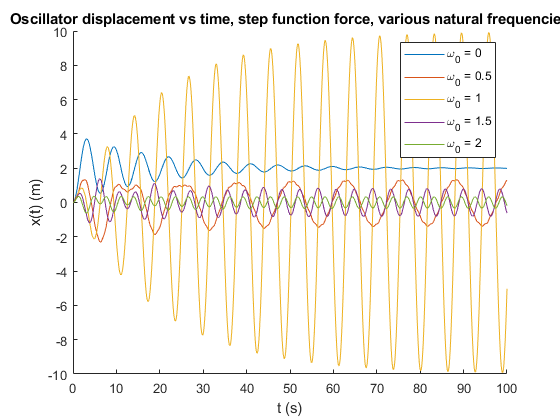


xlabel('t (s)');ylabel('x(t) (m)');
title('Oscillator Displacement v Time, difference of Heavisides, various natural frequencies')
legend(leg)

hold off